# Modism Project 3 - 1A

## Question

On November 24th, 2021, a spacecraft named DART was launched. Its mission is to fly itself into an asteroid to test out weather such an impact could be a feasible method to redirect an earth-threating object. 

In this model, we are **predicting** weather DART would have been able to redirect the Chicxulub impactors (the asteroid hypothesized to have led to the dinosaur extinction) and if so, how many years in advance would DART need to collide to produce a safe trajectory. 

This is an interesting question because it might demonstrate that humans have power to influence cosmic phenome that would otherwise lead to human extinction. Additionally, it could highlight what areas of research are necessary to make DART be effective against larger asteroids.

## Method

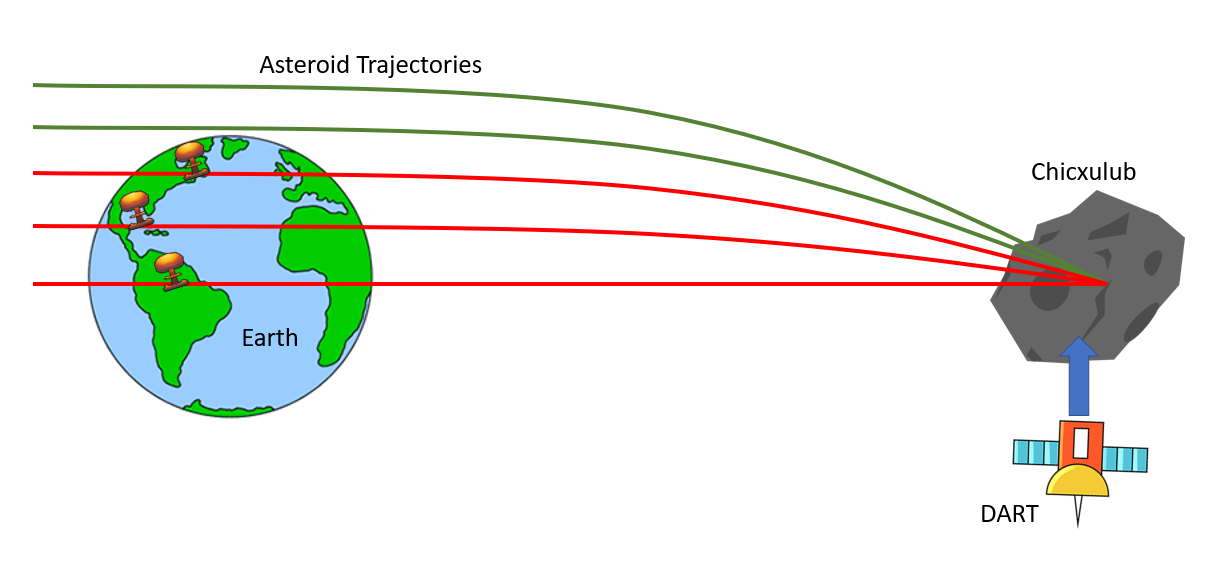

## Results

## Interpretation

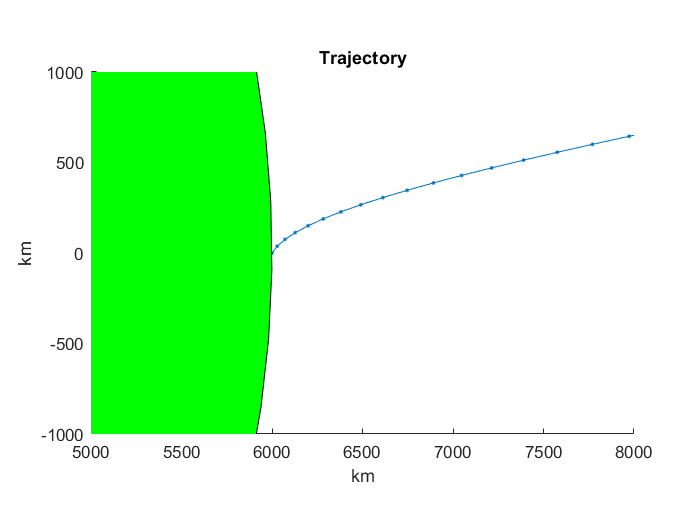

chic_data = chicxulub(0.1, 0.001);  %generate data for the asteriod for 0.01 years are 0.001 hour timesteps
plot_traj(chic_data(1:40,:)); %plot the trajectory
axis([5000 8000 -1000 1000])

dt = 0.01; %hours

years = 10;
hours = years*365*24;
chic_data = chicxulub(hours, dt);  %generate data for the asteriod for 10 years at 0.01 hour timesteps

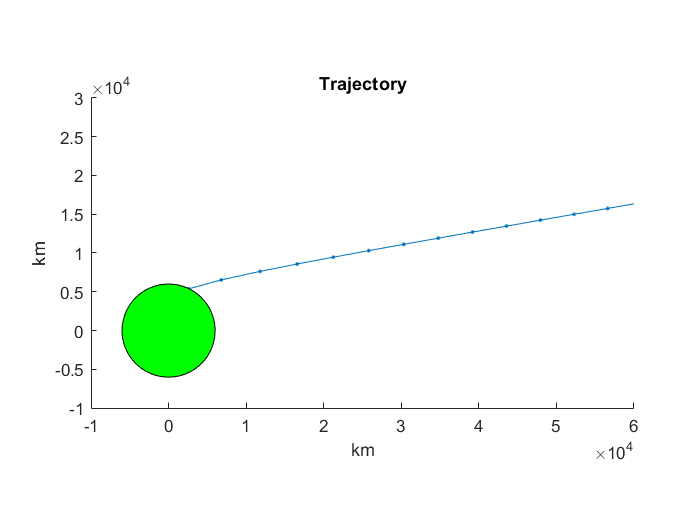


years = 2;
hours = years*365*24;
[t, x, impact] = trajectory(hours, dt, chic_data);  %test collisision detection: calculate trajectory from 2 years hours before impact
plot_traj([t x]);

if isempty(impact)
    disp("No impact!")
else
    disp("Impact!")
end

Impact!


Iteration: In our initial model, we chose an arbitrary trajectory for the Chicxulub impactor where it crashes directly into the Earth. However, we did some research and found the real impact angle and then created a function that calculates a more-realistic trajectory for the impactor. In the first iteration of our model, we parameter-swept the distance from the Earth at which the DART collides with the impactor. In this current interation of our model, we parameter-sweep the time at which the DART collides with the impactor, where the position is determined using the impactor's calculated trajectory

Results:

max_time = 10*365*24;
dt = 0.01;
path = chicxulub(max_time, dt); % calculate the trajectory of the impactor

figure
hold on

impacts = [];


impacts =

     []



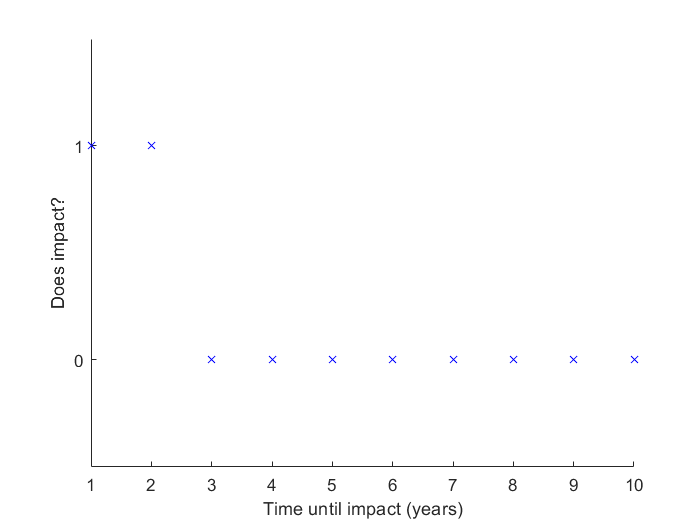


for i=(365*24):(365*24):(365*24*10)
    [~, ~, impact] = trajectory(i, dt, path); % if DART hits at max_time-i, will the impactor impact?
    impacts(end+1) = ~isempty(impact);
    plot(i / (365*24), ~isempty(impact), "-xb")
end

xlabel("Time until impact (years)")

ylabel("Does impact?")
ylim([-0.5 1.5])
yticks([0 1])

hold off

This graph that there are several windows in time where DART will be able to successfully deflect the impactor. This shows that DART would have had to collide with the impactor at least 3 years in advance.